Separar en datos "train" (impares) y datos "validation" (pares)

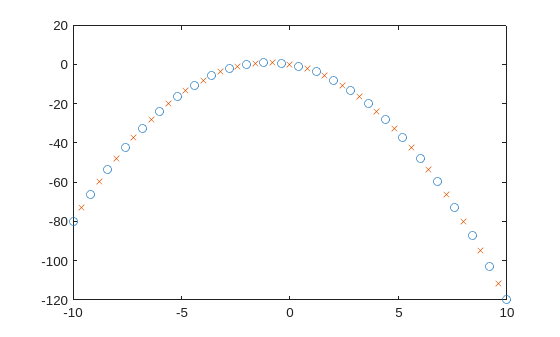

n_puntos = 51;
x = linspace(-10,10,n_puntos)';

y = -2*x-x.^2;

data = [x y];

trndata = data(1:2:n_puntos,:);  % impares -> train
chkdata = data(2:2:n_puntos,:);  % pares  -> validation

figure;

plot(trndata(:,1), trndata(:,2),'o'); hold on;
plot(chkdata(:,1), chkdata(:,2),'x');

Crear FIS

numMFs  = 11;
mfType  = 'gbellmf';     % campana generalizada

fismat = genfis1(trndata, numMFs, mfType);

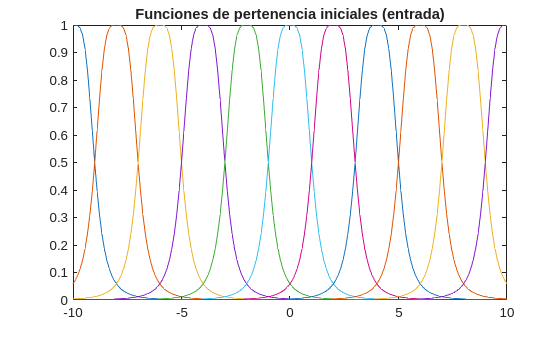

figure;
[xmf, ymf] = plotmf(fismat,'input',1);
plot(xmf, ymf);
title('Funciones de pertenencia iniciales (entrada)');

Entrenar FIS con ANFIS

numEpochs = 60;

[fismat1, trnErr, ss, fismat2, chkErr] = anfis(trndata, fismat, numEpochs, NaN, chkdata);


ANFIS info:
	Number of nodes: 48
	Number of linear parameters: 22
	Number of nonlinear parameters: 33
	Total number of parameters: 55
	Number of training data pairs: 26
	Number of checking data pairs: 25
	Number of fuzzy rules: 11




Start training ANFIS ...

1 	 0.204068 	 0.250691
2 	 0.20265 	 0.249275
3 	 0.201231 	 0.247844
4 	 0.199811 	 0.246397
Step size increases to 0.011000 after epoch 5.
5 	 0.19839 	 0.244937
6 	 0.196967 	 0.243463
7 	 0.195399 	 0.241827
8 	 0.193827 	 0.240177
Step size increases to 0.012100 after epoch 9.
9 	 0.192252 	 0.238513
10 	 0.190673 	 0.236836
11 	 0.18893 	 0.234978
12 	 0.187182 	 0.233107
Step size increases to 0.013310 after epoch 13.
13 	 0.185428 	 0.231224
14 	 0.183667 	 0.229329
15 	 0.181721 	 0.227235
16 	 0.179767 	 0.225129
Step size increases to 0.014641 after epoch 17.
17 	 0.177804 	 0.223014
18 	 0.175832 	 0.220891
19 	 0.173652 	 0.218548
20 	 0.171459 	 0.216199
Step size increases to 0.016105 after epoch 21.
21 	 0.169255 	 0.213844
22 	 0.16704 	 0.211486
23 	 0.164589 	 0.208889
24 	 0.162123 	 0.206292
Step size increases to 0.017716 after epoch 25.
25 	 0.159644 	 0.203695
26 	 0.157151 	 0.2011
27 	 0.154392 	 0.198251
28 	 0.151618 	 0.195407
St

Comprobar RMSE en datos

epoch = 1:numEpochs;

trnOut = evalfis(trndata(:,1), fismat1);        % Comprobar "Train"

trnRMSE = norm(trnOut - trndata(:,2))/sqrt(length(trnOut))

trnRMSE = 0.0177


chkOut = evalfis(chkdata(:,1), fismat2);        % Comprobar "Val"

chkRMSE = norm(chkOut - chkdata(:,2))/sqrt(length(chkOut))

chkRMSE = 0.0933

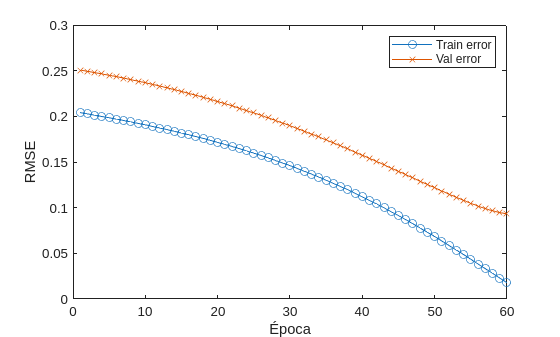


plot(epoch, trnErr, 'o-');
hold on;
plot(epoch, chkErr, 'x-');
hold off
xlabel('Época');
ylabel('RMSE');
legend('Train error','Val error');

Tamaño del Paso del Gradiente

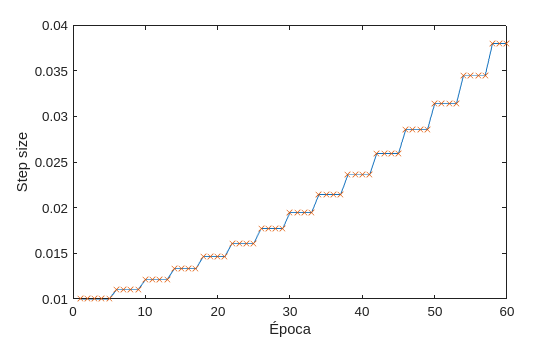

plot(epoch, ss,'-'); 
hold on;
plot(epoch, ss,'x');
hold off
xlabel('Época'); ylabel('Step size');

Funciones de Pertenencia después del entrenamiento

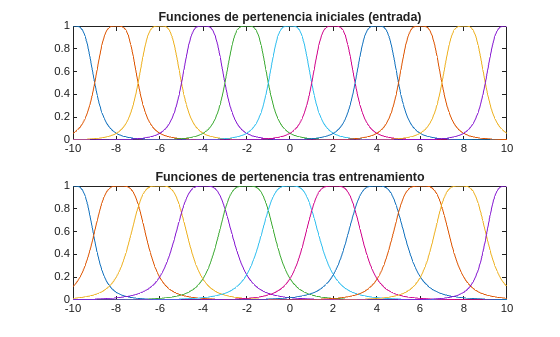

figure;
[xmf2, ymf2] = plotmf(fismat1,'input',1);
subplot(2,1,1)
plot(xmf, ymf);
title('Funciones de pertenencia iniciales (entrada)');
subplot(2,1,2)
plot(xmf2, ymf2);
title('Funciones de pertenencia tras entrenamiento');

Resultados

anfis_y = evalfis(x, fismat1);

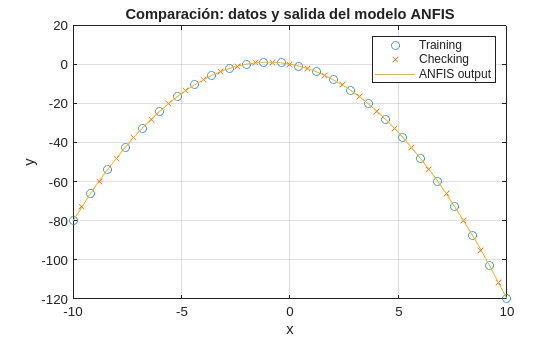


figure;
plot(trndata(:,1), trndata(:,2),'o'); hold on;
plot(chkdata(:,1), chkdata(:,2),'x');
plot(x, anfis_y,'-');
grid on;
legend('Training','Checking','ANFIS output');
xlabel('x'); ylabel('y');
title('Comparación: datos y salida del modelo ANFIS');

anfis_y_init = evalfis(x, fismat);

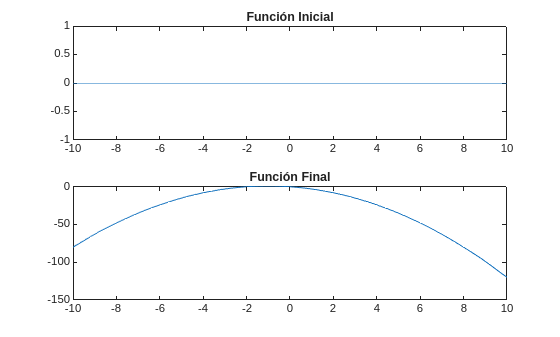


figure;
subplot(2,1,1)
plot(x, anfis_y_init,'-');
title('Función Inicial');
subplot(2,1,2)
plot(x, anfis_y,'-');
title('Función Final');

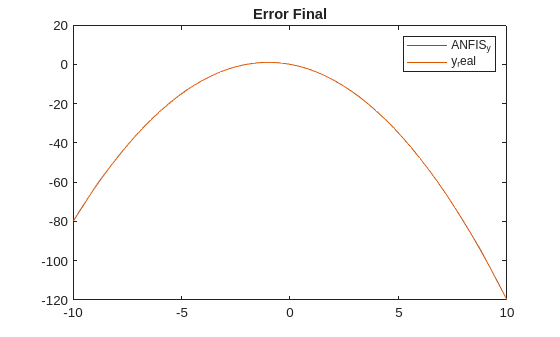


figure;
plot(x, anfis_y,'-');
hold on;
plot(x, y,'-');
hold off;
title('Error Final');
legend('ANFIS_y','y_real');